DIFFERENTIAL STEERING MOBILE

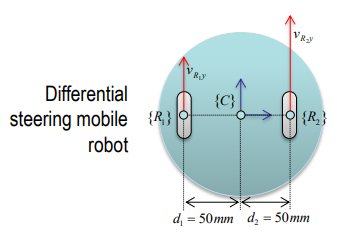

Creamos el Jacobiano sabiendo que son dos ruedas fijas (non-steering).

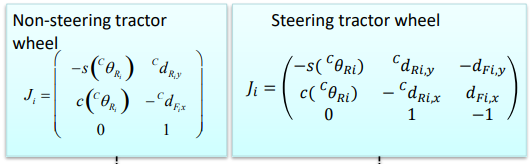

% Sistema {R1}
alphaF1 = 0;
thetaD1 = 0;
alphaR1 = 0;
dR1 = [0 0 0]';
dF1 = [-0.35 0 0]';

CdR1 = rotZ(alphaF1 + thetaD1) * dR1 + dF1

CdR1 =    -0.5000
         0
         0


CthetaR1 = alphaF1 + thetaD1 + alphaR1

CthetaR1 = 0


J1 = [-sin(CthetaR1) CdR1(2) ; cos(CthetaR1) -CdR1(1) ; 0 1]

J1 =          0         0
    1.0000    0.5000
         0    1.0000


% Sistema {R2}
alphaF2 = 0;
thetaD2 = 0;
alphaR2 = 0;
dR2 = [0 0 0]';
dF2 = [0.35 0 0]';

CdR2 = rotZ(alphaF2 + thetaD2) * dR2 + dF2

CdR2 =     0.5000
         0
         0


CthetaR2 = alphaF2 + thetaD2 + alphaR2

CthetaR2 = 0


J2 = [-sin(CthetaR2) CdR2(2) ; cos(CthetaR2) -CdR2(1) ; 0 1]

J2 =          0         0
    1.0000   -0.5000
         0    1.0000


% Composición
A = [eye(3) ; eye(3)];
B = [J1 zeros(3,2) ; zeros(3,2) J2];

% Deslizamiento MCD
syms v1 v2 w1 w2 real
q_dot = [v1 w1 v2 w2]';

x = inv(A'*A)*A'*B*q_dot;
e = omega(A)*B*q_dot;   % Para que no haya deslizamiento, cada elemento = 0.
sol = solve([e(2) == 0, e(3) == 0], [w1,w2]);
w1 = sol.w1

$$w1 = v_{2}-v_{1}$$

w2 = sol.w2

$$w2 = v_{2}-v_{1}$$

eval(e); % Vemos como cambia e al aplicar las condiciones de no deslizamiento

eval(x)

$$ans = \left(\begin{array}{c} 0\\ \frac{v_{1}}{2}+\frac{v_{2}}{2}\\ v_{2}-v_{1} \end{array}\right)$$

%Vx = 0
%Vy = v1/2 + v2/2
%Wz = 10v2 - 10 v1

% VC = DK * q
DK = [0 0 0 0 ; 1/2 0 1/2 0 ; -10 0 10 0];

syms Vx Vy Wz d real

VC = [Vx, Vy, Wz]';

x = inv(B'*B)*B'*A*VC;
e = omega(B)*A*VC;   % Para que no haya deslizamiento, cada elemento = 0.
sol = solve([e(1) == 0], [Vx]);
Vx = sol
eval(e); % Vemos como cambia e al aplicar las condiciones de no deslizamiento

IK = eval(x)

IK =     0.5000
    1.0000
    1.5000
    1.0000


%v1 = Vy - Wz/20
%w1 = Wz 
%v2 = Vy + Wz/20
%w2 = Wz

% q = IK * VC
IK = [0 1 -1/20 ; 0 0 1 ; 0 1 1/20 ; 0 0 1];

Funciones

function RZ=rotZ(theta)

s=sin(theta); c=cos(theta);
if isnumeric(theta)
    if abs(c)<1e-10
        c=0;
    end
    if abs(s)<1e-10
         s=0;
    end
end 

RZ=[c,-s,0;
    s,c,0;
    0,0,1];
end